**Velocity**

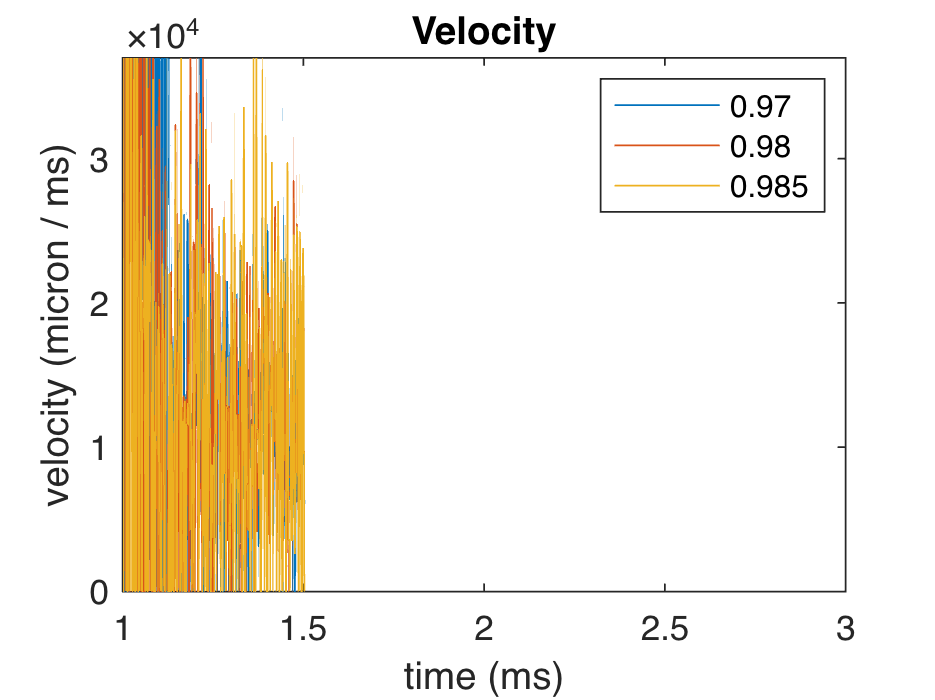

fpms = 581; %-- frames per millisecond
totalTime = size(experiment1, 3)/fpms;
msPerFrame = 1/fpms;
micronsPerXPixel = 160;
micronsPerZPixel = 592;
timeSmoothing = 3;
xSmoothing = 21;
zSmoothing  = 21;

thresholds = [0.97;0.98;0.985];
velocities = [{} {} {}];
areas = [{} {} {}];
perimeters = [{} {} {}];
betas = [{} {} {}];

for i=1:length(thresholds)
    current = SmoothExperiment(experiment1,timeSmoothing,thresholds(i), zSmoothing, xSmoothing);
    scaled = ScaleImage(current,micronsPerZPixel/micronsPerXPixel);
    [Area,Perimeter,Velocity,Beta] = GetParameters(scaled);
    velocities(i) = {Velocity * (micronsPerXPixel/msPerFrame)} ;
    areas(i) = {Area * micronsPerXPixel * micronsPerXPixel} ;
    perimeters(i) = {Perimeter * micronsPerXPixel} ;
    betas(i) = {Beta};
end

timeLine = (1:size(experiment1,3)) / fpms;

for i=1:length(thresholds)
    plot(timeLine,velocities{i});
    hold on;
end
hold off;
legend("0.97", "0.98", "0.985");
title("Velocity");
xlabel("time (ms)");
ylabel("velocity (micron / ms)");
xlim([1 3]);
ylim([0 37000]);

**Area**

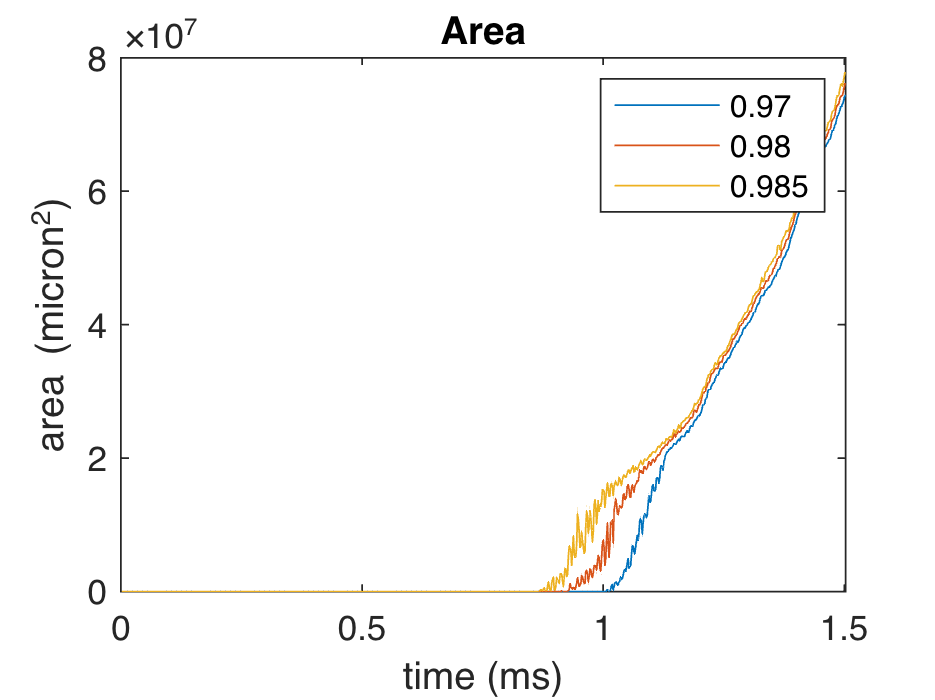

for i=1:length(thresholds)
    plot(timeLine,areas{i});
    hold on;
end
hold off;
title("Area");
xlabel("time (ms)");
ylabel("area (micron^2)");
legend("0.97", "0.98", "0.985");

**Perimeter**

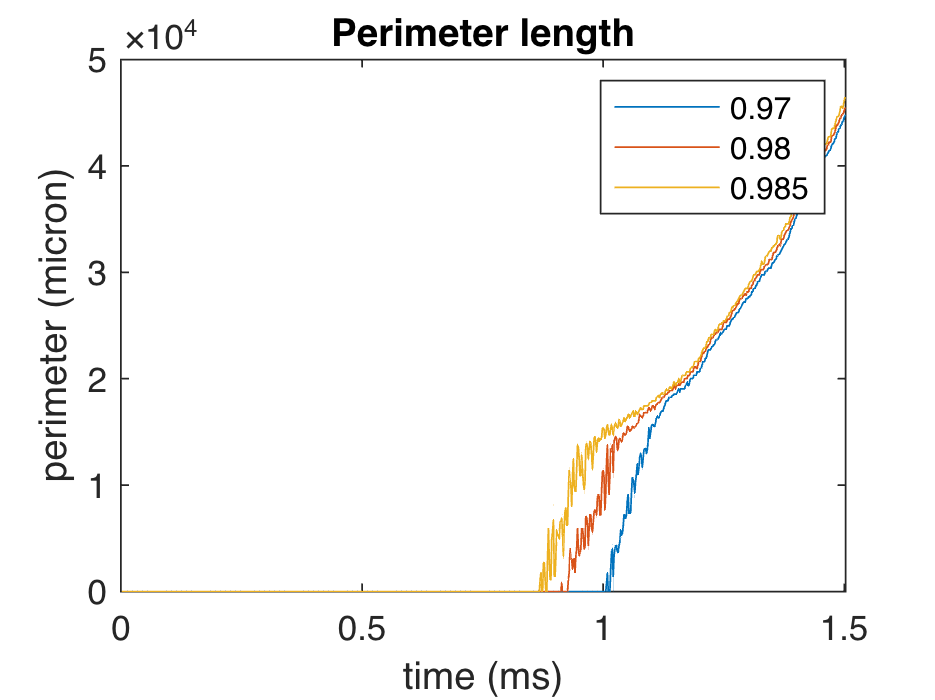

for i=1:length(thresholds)
    plot(timeLine,perimeters{i});
    hold on;
end
hold off;
title("Perimeter length");
xlabel("time (ms)");
ylabel("perimeter (micron)");
legend("0.97", "0.98", "0.985");

**Beta**

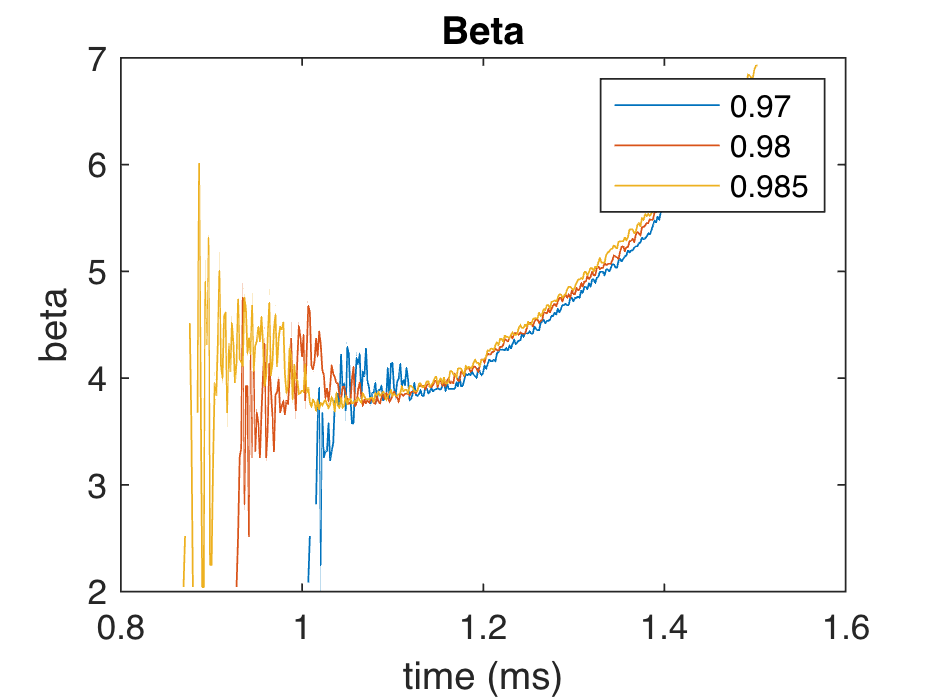

for i=1:length(thresholds)
    plot(timeLine,betas{i});
    hold on;
end
hold off;
title("Beta");
xlabel("time (ms)");
ylabel("beta");
legend("0.97", "0.98", "0.985");